# Laboratorium 9

Karolina Piotrowska

## Wstęp

Celem laboratorium było zapoznanie się z podstawowymi parametrami sygnałów cyfrowych, takimi jak:

- wartość średnia

- średnia kwadratowa - RMS

- współczynnik szczytu

- współczynnik peak-to-peak

- wartość maksymalna i minimalna

- wariancja

- odchylenie standardowe

- energia sygnału dyskretnego

- średnia moc sygnału dyskretnego

- RSS - root sum square

## Rozwiązanie 

load dane.mat

### Zadanie 1

fprintf('Średnia X: %f\n', mean(X));

Średnia X: 1.333333


fprintf('Średnia wiatrak: %f\n', mean(wiatrak_data));

Średnia wiatrak: -0.000024


fprintf('Średnia przekladnia: %f\n', mean(przekladnia_data));

Średnia przekladnia: -0.000422


fprintf('\n')

### Zadanie 2

fprintf('RMS X: %f\n', rms(X));

RMS X: 1.825742


fprintf('RMS wiatrak: %f\n', rms(wiatrak_data));

RMS wiatrak: 0.185525


fprintf('RMS przekladnia: %f\n', rms(przekladnia_data));

RMS przekladnia: 0.141515


fprintf('\n')

### Zadanie 3

fprintf('Współczynnik szczytu X: %f\n', peak2rms(X));

Współczynnik szczytu X: 1.643168


fprintf('Współczynnik szczytu wiatrak: %f\n', peak2rms(wiatrak_data));

Współczynnik szczytu wiatrak: 4.277809


fprintf('Współczynnik szczytu przekladnia: %f\n', peak2rms(przekladnia_data));

Współczynnik szczytu przekladnia: 4.701791


fprintf('\n')

### Zadanie 4

fprintf('peak2peak X: %f\n', peak2peak(X));

peak2peak X: 3.000000


fprintf('peak2peak wiatrak: %f\n', peak2peak(wiatrak_data));

peak2peak wiatrak: 1.575714


fprintf('peak2peak przekladnia: %f\n', peak2peak(przekladnia_data));

peak2peak przekladnia: 1.266174


### Zadanie 5

fprintf('min X: %f\nmax X: %f\n\n', min(X), max(X));

min X: 0.000000
max X: 3.000000



fprintf('min wiatrak: %f\nmax wiatrak: %f\n\n', min(wiatrak_data), max(wiatrak_data));

min wiatrak: -0.782074
max wiatrak: 0.793640



fprintf('min przekladnia: %f\nmax przekladnia: %f\n\n', min(przekladnia_data), max(przekladnia_data));

min przekladnia: -0.600800
max przekladnia: 0.665375



### Zadanie 6

fprintf('Wariancja X: %f\n', var(X));

Wariancja X: 2.333333


fprintf('Wariancja wiatrak: %f\n', var(wiatrak_data));

Wariancja wiatrak: 0.034420


fprintf('Wariancja przekladnia: %f\n', var(przekladnia_data));

Wariancja przekladnia: 0.020027


fprintf('\n')

### Zadanie 7

fprintf('Odchylenie standardowe X: %f\n', std(X));

Odchylenie standardowe X: 1.527525


fprintf('Odchylenie standardowe wiatrak: %f\n', std(wiatrak_data));

Odchylenie standardowe wiatrak: 0.185527


fprintf('Odchylenie standardowe przekladnia: %f\n', std(przekladnia_data));

Odchylenie standardowe przekladnia: 0.141516


fprintf('\n')

### Zadanie 8

ex = sum(abs(X).^2);
ew = sum(abs(wiatrak_data).^2);
ep = sum(abs(przekladnia_data).^2);
fprintf('Emergia X: %f\n', ex);

Emergia X: 10.000000


fprintf('Emergia wiatrak: %f\n', ew);

Emergia wiatrak: 1517.899325


fprintf('Emergia przekladnia: %f\n', ep);

Emergia przekladnia: 883.170409


fprintf('\n')

### Zadanie 9

t = 0 : 0.001 : 1-0.001;
Xc = cos(2*pi*100*t);
fprintf('Moc średnia X: %f\n', bandpower(X));

Moc średnia X: 3.333333


fprintf('Moc średnia wiatrak: %f\n', bandpower(wiatrak_data));

Moc średnia wiatrak: 0.034419


fprintf('Moc średnia przekladnia: %f\n', bandpower(przekladnia_data));

Moc średnia przekladnia: 0.020027


fprintf('Moc średnia cosinusa: %f\n', bandpower(Xc));

Moc średnia cosinusa: 0.500000


fprintf('\n')

### Zadanie 10

fprintf('RSS X: %f\n', rssq(X));

RSS X: 3.162278


fprintf('RSS wiatrak: %f\n', rssq(wiatrak_data));

RSS wiatrak: 38.960227


fprintf('RSS przekladnia: %f\n', rssq(przekladnia_data));

RSS przekladnia: 29.718183


fprintf('\n')

### Zadanie 11

Funkcja seqperiod znajduje najkrótszy powtarzający się ciąg elementów w wektorze.

X1=[4 0 1 6;
    2 0 2 7;
    4 0 1 5;
    2 0 5 6]; 

X2 = [4 0 1 6; 2 0 2 7; 4 0 1 5; 2 0 5 6; 1 0 1 7];
fprintf('Sequence period 1: %f\n\n', seqperiod(X1));

Sequence period 1: 2.000000

Sequence period 1: 1.000000

Sequence period 1: 4.000000

Sequence period 1: 3.000000



fprintf('Sequence period 2: %f\n', seqperiod(X2));

Sequence period 2: 5.000000
Sequence period 2: 1.000000
Sequence period 2: 4.000000
Sequence period 2: 3.000000


### Zadanie 12

W zadaniach 12-18 należało użyć funkcji findpeaks do znalezienia maksimów lokalnych.

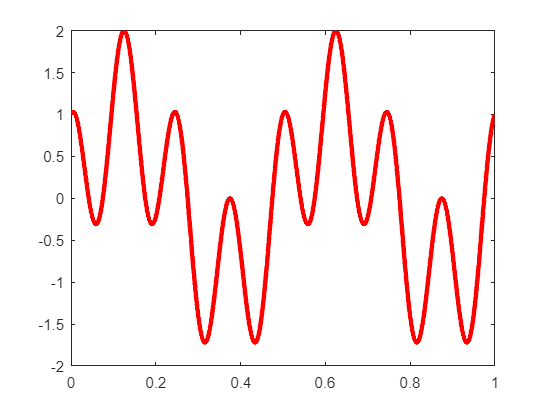

fs=5000;
t=0:(1/fs):1;
X=sin(2*pi*2*t);
Y=cos(2*pi*8*t);
s=X+Y;
plot(t, s, 'r', 'LineWidth', 3);

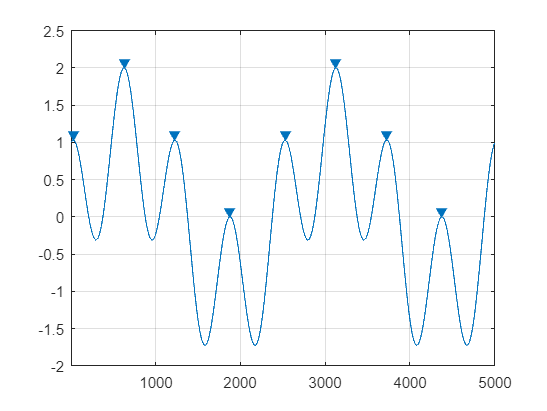

findpeaks(s);

[py, px] = findpeaks(s);

### Zadanie 13

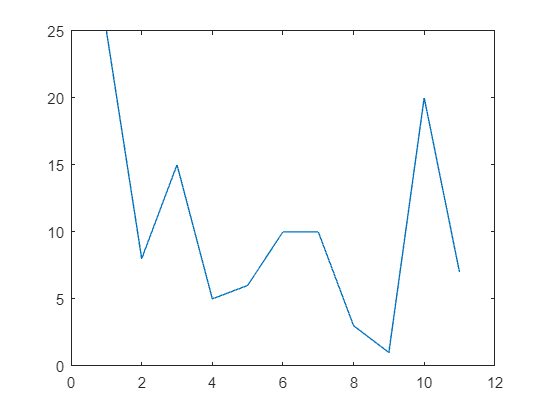

s = [25 8 15 5 6 10 10 3 1 20 7];
plot(s)

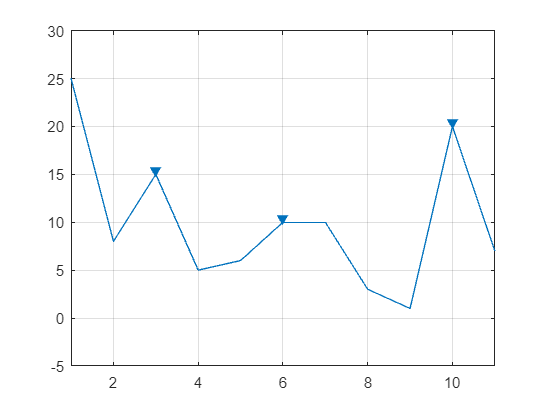

findpeaks(s)

[py, px] = findpeaks(s);

### Zadanie 14

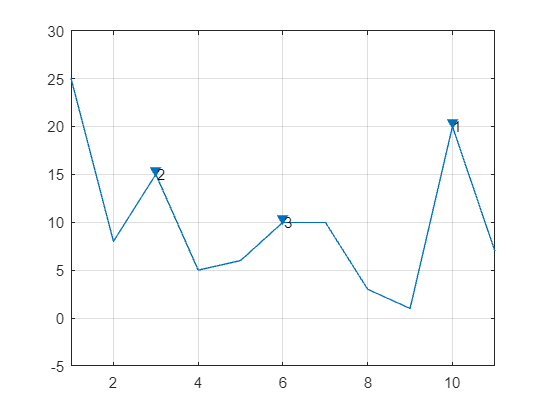

[PEAKS_s, lokalizacja] = findpeaks(s,'SortStr','descend');
text(lokalizacja +.02, PEAKS_s,num2str((1:numel(PEAKS_s))'))

### Zadanie 15

x= [1, 2, 3,4,5,6,7,8,9,10,11];
s = [25 8 15 5 6 10 10 3 1 20 7];
th = 5;
plot(x,s)

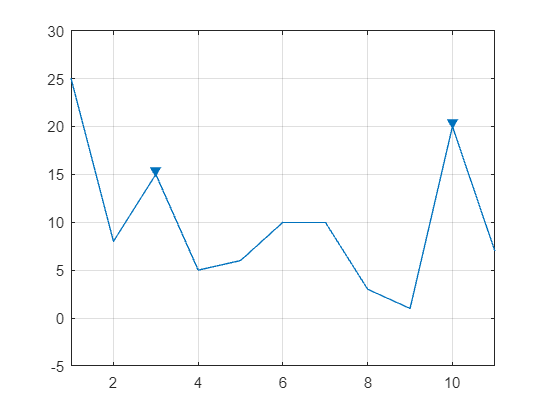

findpeaks(s, 'Threshold', th)

### Zadanie 16

mph = 12;
findpeaks(s, 'MinPeakHeight', mph);

### Zadanie 17

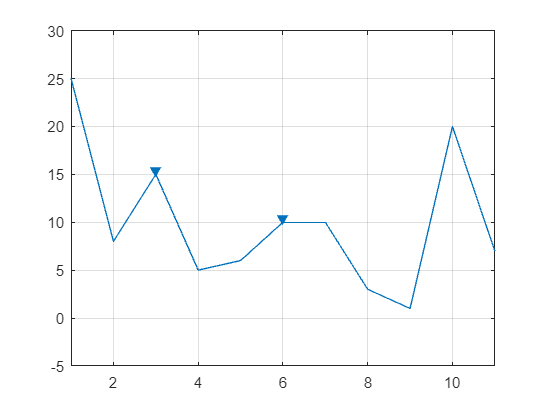

findpeaks(s, 'NPeaks', 2)

### Zadanie 18

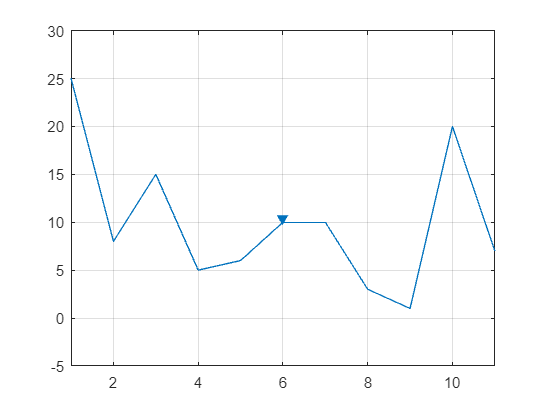

findpeaks(s, 'MinPeakWidth', 1)

### Zadanie 19

load rmsy.mat;

% wzorce
rms_w20 = rms(w20);
rms_w21 = rms(w21);
rms_p20 = rms(p20);
rms_p21 = rms(p21);

% testowe
rms_w23 = rms(w23);
rms_w24 = rms(w24);
rms_p23 = rms(p23);
rms_p24 = rms(p24);

Dw_23_20 = sum(abs(rms_w23 - rms_w20));
Dw_23_21 = sum(abs(rms_w23 - rms_w21));
Dw_24_20 = sum(abs(rms_w24 - rms_w20));
Dw_24_21 = sum(abs(rms_w24 - rms_w21));

Dp_23_20 = sum(abs(rms_p23 - rms_p20));
Dp_23_21 = sum(abs(rms_p23 - rms_p21));
Dp_24_20 = sum(abs(rms_p24 - rms_p20));
Dp_24_21 = sum(abs(rms_p24 - rms_p21));

D_w23_p21 = sum(abs(rms_w23 - rms_p21));

## **Pytania**

**1) Jakie są podstawowe parametry sygnałów?**

- wartość średnia

- średnia kwadratowa - RMS

- współczynnik szczytu

- współczynnik peak-to-peak

- wartość maksymalna i minimalna

- wariancja

- odchylenie standardowe

- energia sygnału dyskretnego

- średnia moc sygnału dyskretnego

- RSS - root sum square

**2) Do czego mogą się przydać parametry sygnałów? Gdzie mogą być zastosowane? **

Klasyfikacja sygnałów cyfrowych, ich porównywanie; badanie sygnałów, prace badawcze.

**3) Co by się stało gdybyśmy dodali do siebie wartości: RMS, RSS i maksymalną sygnału - y=xRMS+xRSS+xMAX. Czy taka wartość będzie dla nas użyteczna? Odpowiedź uzasadnić.  **

Te parametry są ze sobą ściśle skorelowane, więc nie ma potrzeby używania ich wszystkich na raz.

**4) Co takiego robi funkcja findpeaks()?**

Znajduje maksima lokalne sygnału.

## Wnioski

Laboratorium pozwoliło zapoznać się z parametrami sygnałów cyfrowych, sposobami ich obliczania w środowisku Matlab, ich zastosowaniami i przykładowym wykorzystaniem.